# Example: Interface Parameters

When the `.calculate` method of ElasticMatrix is used the stresses and displacements at every interface of the multi-layered medium is calculated. These can be plotted using the `.plotInterfaceParameters` method.

## Initialize ElasticMatrix

This is example will use a three layered Medium.

% Initialize Medium object:
my_medium = Medium('PVDF',Inf,'glass',0.001,'aluminium',Inf);

% Initialize ElasticMatrix object:
model = ElasticMatrix(my_medium);

## Setting Parameters

% Set some parameters:
model.setFrequency(1e6);
model.setAngle(linspace(0,89,100));

## Calculate and Plot Interface Parameters

A new figure will be plotted for every interface, here there are two interfaces so there are two figures plotted.

% Run the model: 
model.calculate;

... calculating matrix method ... 
... frequency-angle calculation ...
... done ... 


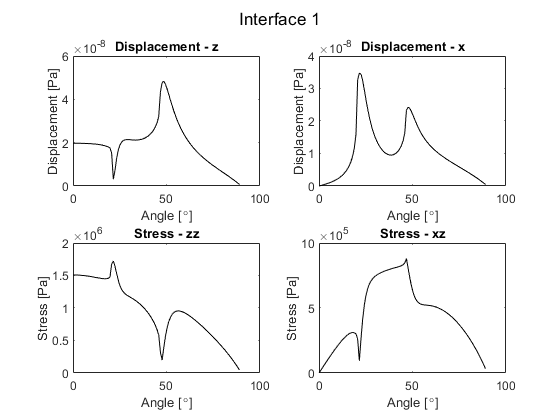

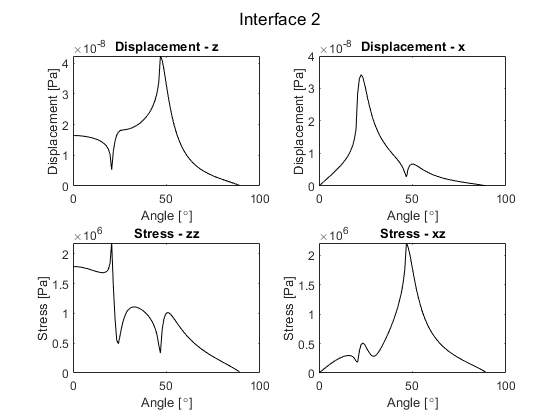


% Plot the interface parameters:
model.plotInterfaceParameters;

## About

This file is part of the ElasticMatrix toolbox. Copyright (c) 2019 Danny Ramasawmy.

This file is part of ElasticMatrix. ElasticMatrix is free software: you can redistribute it and/or modify it under the terms of the GNU Lesser General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

ElasticMatrix is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU Lesser General Public License for more details.

You should have received a copy of the GNU Lesser General Public License along with ElasticMatrix. If not, see [http://www.gnu.org/licenses/](http://www.gnu.org/licenses/).